## PART 1: KINEMATICS

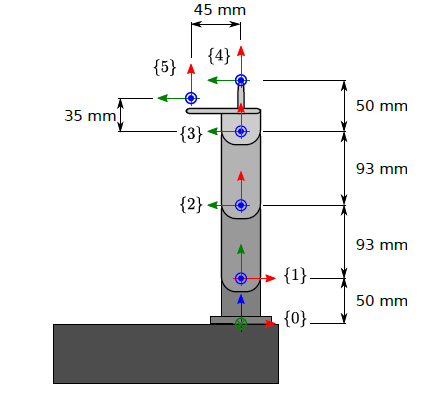

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% from DH convention we get:

% {0} -> {1}
T01 = [cos(theta0), 0, sin(theta0), 0;
       sin(theta0), 0, -cos(theta0), 0;
       0, 1, 0, L01;
       0, 0, 0, 1];

% {1} -> {2}
T12 = [cos(theta1), -sin(theta1), 0, L12*sin(theta1);
       sin(theta1), cos(theta1), 0, L12*sin(theta1);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {2} -> {3}
T23 = [cos(theta2), -sin(theta2), 0, L23*sin(theta2);
       sin(theta2), cos(theta2), 0, L23*sin(theta2);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {4}     
T34 = [cos(theta3), -sin(theta3), 0, L34*sin(theta3);
       sin(theta3), cos(theta3), 0, L34*sin(theta3);
       0, 0, 1, 0;
       0, 0, 0, 1];

% {3} -> {5}
T35 = [1, 0, 0, L35;
       0, 1, 0, L45;
       0, 0, 1, 0;
       0, 0, 0, 1];

% Transformation from {0} to {4}
T04 = simplify(T01*T12*T23*T34)

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(\theta_{0}\right) & -\sigma_{1}\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right)\,\sigma_{3}\\ \sigma_{2}\,\sin\left(\theta_{0}\right) & -\sigma_{1}\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & -\sin\left(\theta_{0}\right)\,\sigma_{3}\\ \sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{1}\right)+\sigma_{5}+\sigma_{4}+50\,\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+50\,\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{3}=\sigma_{4}-\sigma_{5}-93\,\sin\left(\theta_{1}\right)+50\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+50\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+50\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-50\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=93\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{5}=93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = simplify(T01*T12*T23*T35)

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right) & \cos\left(\theta_{0}\right)\,\sigma_{1}\\ \cos\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\,\sin\left(\theta_{0}\right) & -\cos\left(\theta_{0}\right) & \sin\left(\theta_{0}\right)\,\sigma_{1}\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & 93\,\sin\left(\theta_{1}\right)+45\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+128\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+35\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+48\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=93\,\sin\left(\theta_{1}\right)+35\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+48\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-45\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-128\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

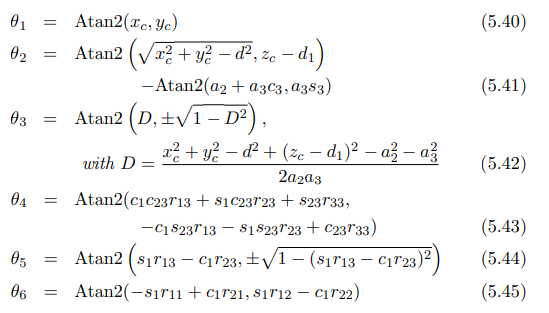

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





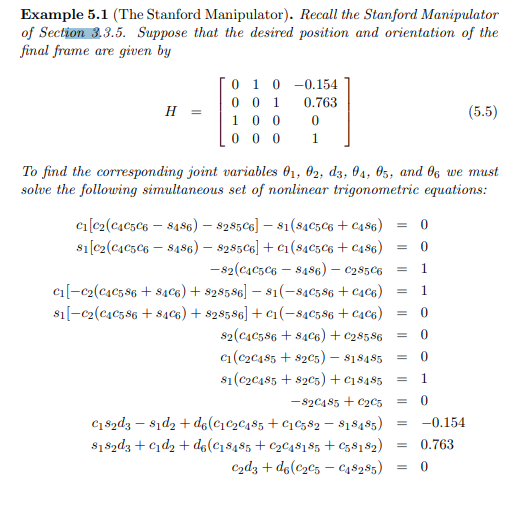

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

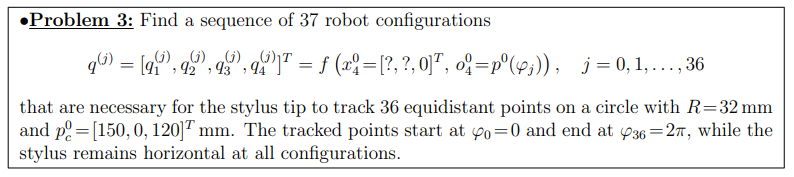


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832




dy = cos(angles)*50;
dz = sin(angles)*50;

x = xc*ones(1,length(angles))

x =    150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150


y = yc + dy

y =   150.0000  149.2404  146.9846  143.3013  138.3022  132.1394  125.0000  117.1010  108.6824  100.0000   91.3176   82.8990   75.0000   67.8606   61.6978   56.6987   53.0154   50.7596   50.0000   50.7596   53.0154   56.6987   61.6978   67.8606   75.0000   82.8990   91.3176  100.0000  108.6824  117.1010  125.0000  132.1394  138.3022  143.3013  146.9846  149.2404  150.0000


z = zc + dz

z =   100.0000  108.6824  117.1010  125.0000  132.1394  138.3022  143.3013  146.9846  149.2404  150.0000  149.2404  146.9846  143.3013  138.3022  132.1394  125.0000  117.1010  108.6824  100.0000   91.3176   82.8990   75.0000   67.8606   61.6978   56.6987   53.0154   50.7596   50.0000   50.7596   53.0154   56.6987   61.6978   67.8606   75.0000   82.8990   91.3176  100.0000





% Taras insert magic here. Please transform thew set of
% coordinates[x,y,z](37 points of each) into a set of coordinates

% Stylus always parallel to the ground
x04 = [0, 0, 1];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

Angles:
 theta1: 
    0.7854

 theta2: 
    0.8279

 theta3: 
   63.5604

 theta4: 
  -62.8176

Angles:
 theta1: 
    0.7829

 theta2: 
   -0.9144

 theta3: 
   60.0129

 theta4: 
  -57.5277

Angles:
 theta1: 
    0.7752

 theta2: 
    0.1828

 theta3: 
   55.8735

 theta4: 
  -54.4855

Angles:
 theta1: 
    0.7626

 theta2: 
    1.0332

 theta3: 
   51.2510

 theta4: 
  -50.7133

Angles:
 theta1: 
    0.7448

 theta2: 
    1.7196

 theta3: 
   46.3092

 theta4: 
  -46.4580

Angles:
 theta1: 
    0.7222

 theta2: 
   -0.7827

 theta3: 
   41.2803

 theta4: 
  -38.9268

Angles:
 theta1: 
    0.6947

 theta2: 
   -0.0280

 theta3: 
   36.4888

 theta4: 
  -34.8900

Angles:
 theta1: 
    0.6628

 theta2: 
    1.0665

 theta3: 
   32.3825

 theta4: 
  -31.8782

Angles:
 theta1: 
    0.6270

 theta2: 
   -0.3551

 theta3: 
   29.5320

 theta4: 
  -27.6061

Angles:
 theta1: 
    0.5880

 theta2: 
   -0.8707

 theta3: 
   28.4985

 theta4: 
  -26.0569

Angles:
 theta1: 
    0.5469

 theta2: 




%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


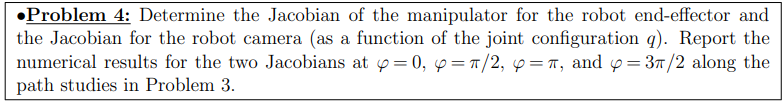

% if you need help figuring out the angles contact Palli
clc
disp("helloo")

helloo


phi = [0 pi/2 pi 3*pi/2];
%phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end

T04 =    -1.0000   -0.0000         0 -197.3596
         0         0   -1.0000         0
    0.0000   -1.0000         0   22.1391
         0         0         0    1.0000


T03 =     0.2002    0.9798         0 -139.5575
         0         0   -1.0000         0
   -0.9798    0.2002         0  -16.0527
         0         0         0    1.0000


T02 =     0.7293    0.6842         0  -63.6316
         0         0   -1.0000         0
   -0.6842    0.7293         0  -13.6316
         0         0         0    1.0000


J =          0   27.8609  -35.7706  -38.1918
 -197.3596         0         0         0
         0 -197.3596 -133.7280  -57.8021
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


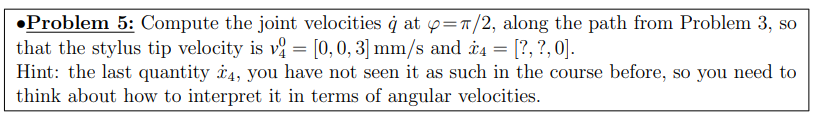

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:3%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34
    T03=T01*T12*T23
    T02=T01*T12
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1*(1/max(k1));
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2*(1/max(k2));
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3*(1/max(k3));
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4*(1/max(k4));

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    v04 = cross(w04,o4)
    




end

T04 =    -1.0000    0.0000         0 -204.3849
         0         0   -1.0000         0
   -0.0000   -1.0000         0   48.4383
         0         0         0    1.0000


T03 =    -0.1809    0.9835         0 -164.9152
         0         0   -1.0000         0
   -0.9835   -0.1809         0   -8.8205
         0         0         0    1.0000


T02 =     0.5248    0.8512         0  -79.1660
         0         0   -1.0000         0
   -0.8512    0.5248         0  -29.1660
         0         0         0    1.0000


v04 =    NaN   NaN   NaN


T04 =    -1.0000    0.0000         0 -193.1261
         0         0   -1.0000         0
   -0.0000   -1.0000         0   59.9509
         0         0         0    1.0000


T03 =    -0.8046    0.5938         0 -199.3864
         0         0   -1.0000         0
   -0.5938   -0.8046         0   18.4346
         0         0         0    1.0000


T02 =     0.3055    0.9522         0  -88.5537
         0         0   -1.0000         0
   -0.9522    0.3055         0  -38.5537
         0         0         0    1.0000


v04 =    NaN   NaN   NaN


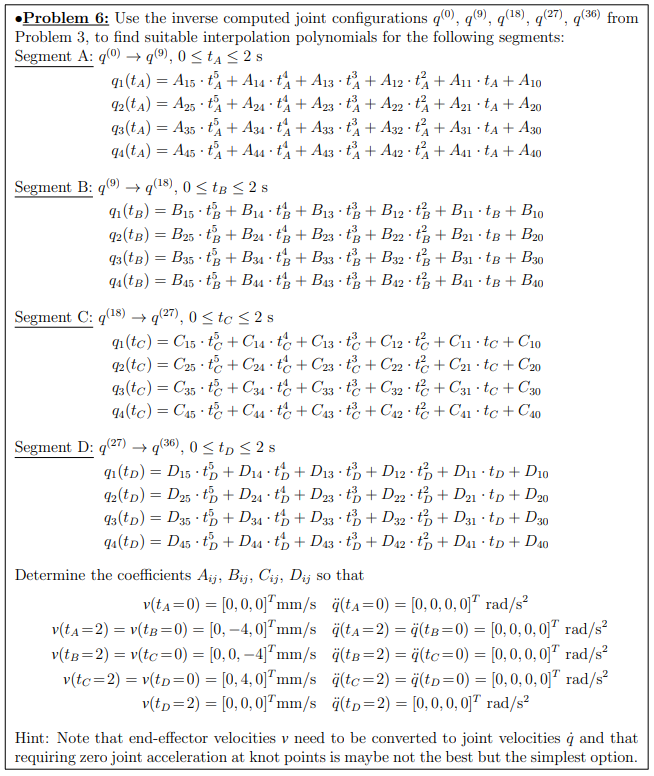

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is
                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);

o04 =    29.0420
   19.3613
   35.6904


o14 =    34.9041
         0
   35.6904


o24 =    11.5436
  -35.9139
         0


o34 = 1.0e+03 *

    0.1231
    1.3028
         0


J =   -19.3613  -35.6904         0         0
   29.0420         0         0         0
         0   34.9041   11.5436  123.1239
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JB = getJacobian(19);

o04 =   200.6353
   66.8784
  114.2345


o14 =   211.4882
         0
  114.2345


o24 =    95.7397
  199.2166
         0


o34 = 1.0e+03 *

    0.1430
    3.1409
         0


J =   -66.8784 -114.2345         0         0
  200.6353         0         0         0
         0  211.4882   95.7397  142.9949
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JC = getJacobian(28);

o04 =    37.1254
   24.7503
   28.2022


o14 =    44.6192
         0
   28.2022


o24 =   -16.2524
  -46.9242
         0


o34 = 1.0e+03 *

    0.1397
    3.4739
         0


J =   -24.7503  -28.2022         0         0
   37.1254         0         0         0
         0   44.6192  -16.2524  139.7415
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JD = getJacobian(37);

o04 =   149.5447
  149.5447
  114.2345


o14 =   211.4882
         0
  114.2345


o24 =    95.7397
  199.2166
         0


o34 = 1.0e+03 *

    0.1430
    3.1409
         0


J =  -149.5447 -114.2345         0         0
  149.5447         0         0         0
         0  211.4882   95.7397  142.9949
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


%jaconbian matrix for calculating joint velocities ˙q
v0=0;
I=eye(4);
b=[0; 0; 0; 0];
JAp=inv(JA'*JA)*JA';
JBp=inv(JB'*JB)*JB';
JCp=inv(JC'*JC)*JC';
JDp=inv(JD'*JD)*JD';
vA=JAp*VA+(I-JAp*JA)*b;
vB=JBp*VB+(I-JBp*JB)*b;
vC=JCp*VC+(I-JCp*JC)*b;
vD=JDp*VD+(I-JDp*JD)*b;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);
D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

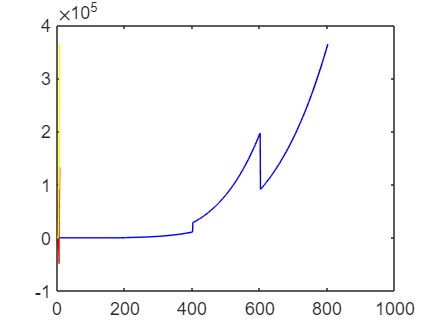

x = 0:0.01:8;
q1A = A1(6) * x.^5 + A1(5) * x.^4 + A1(4) * x.^3 + A1(3) * x.^2 + A1(2) * x + A1(1);
q2A = A2(6) * x.^5 + A2(5) * x.^4 + A2(4) * x.^3 + A2(3) * x.^2 + A2(2) * x + A2(1);
q3A = A3(6) * x.^5 + A3(5) * x.^4 + A3(4) * x.^3 + A3(3) * x.^2 + A3(2) * x + A3(1);
q4A = A4(6) * x.^5 + A4(5) * x.^4 + A4(4) * x.^3 + A4(3) * x.^2 + A4(2) * x + A4(1);

q1B = B1(6) * x.^5 + B1(5) * x.^4 + B1(4) * x.^3 + B1(3) * x.^2 + B1(2) * x + B1(1);
q2B = B2(6) * x.^5 + B2(5) * x.^4 + B2(4) * x.^3 + B2(3) * x.^2 + B2(2) * x + B2(1);
q3B = B3(6) * x.^5 + B3(5) * x.^4 + B3(4) * x.^3 + B3(3) * x.^2 + B3(2) * x + B3(1);
q4B = B4(6) * x.^5 + B4(5) * x.^4 + B4(4) * x.^3 + B4(3) * x.^2 + B4(2) * x + B4(1);

q1C = C1(6) * x.^5 + C1(5) * x.^4 + C1(4) * x.^3 + C1(3) * x.^2 + C1(2) * x + C1(1);
q2C = C2(6) * x.^5 + C2(5) * x.^4 + C2(4) * x.^3 + C2(3) * x.^2 + C2(2) * x + C2(1);
q3C = C3(6) * x.^5 + C3(5) * x.^4 + C3(4) * x.^3 + C3(3) * x.^2 + C3(2) * x + C3(1);
q4C = C4(6) * x.^5 + C4(5) * x.^4 + C4(4) * x.^3 + C4(3) * x.^2 + C4(2) * x + C4(1);

q1D = D1(6) * x.^5 + D1(5) * x.^4 + D1(4) * x.^3 + D1(3) * x.^2 + D1(2) * x + D1(1);
q2D = D2(6) * x.^5 + D2(5) * x.^4 + D2(4) * x.^3 + D2(3) * x.^2 + D2(2) * x + D2(1);
q3D = D3(6) * x.^5 + D3(5) * x.^4 + D3(4) * x.^3 + D3(3) * x.^2 + D3(2) * x + D3(1);
q4D = D4(6) * x.^5 + D4(5) * x.^4 + D4(4) * x.^3 + D4(3) * x.^2 + D4(2) * x + D4(1);
figure; % Create a new figure window
y1 = q1A.*(x>=0&x<=2) + q1B.*(x>2&x<=4) + q1C.*(x>4&x<=6) + q1D.*(x>6&x<=8);
plot(y1, 'b');
hold on
y2 = q2A.*(x>=0&x<=2) + q2B.*(x>2&x<=4) + q2C.*(x>4&x<=6) + q2D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q3A.*(x>=0&x<=2) + q3B.*(x>2&x<=4) + q3C.*(x>4&x<=6) + q3D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q4A.*(x>=0&x<=2) + q4B.*(x>2&x<=4) + q4C.*(x>4&x<=6) + q4D.*(x>6&x<=8);
plot(x, y1, 'y'); 

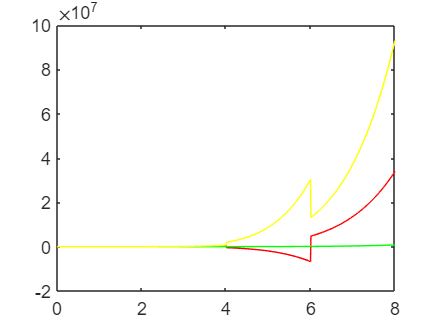

%%seven knot points
A71 = getConstant7(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A72 = getConstant7(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A73 = getConstant7(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A74 = getConstant7(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A7 = [A71 A72 A73 A74];
 
B71 = getConstant7(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B72 = getConstant7(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B73 = getConstant7(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B74 = getConstant7(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B7 = [B71 B72 B73 B74];

C71 = getConstant7(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C72 = getConstant7(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C73 = getConstant7(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C74 = getConstant7(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C7 = [C71 C72 C73 C74];

D71 = getConstant7(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);
D72 = getConstant7(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D73 = getConstant7(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D74 = getConstant7(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D7 = [D71 D72 D73 D74];

x = 0:0.01:8;
q71A = A71(8) * x.^7 + A71(7) * x.^6 + A71(6) * x.^5 + A71(5) * x.^4 + A71(4) * x.^3 + A71(3) * x.^2 + A71(2) * x + A71(1);
q72A = A72(8) * x.^7 + A72(7) * x.^6 + A72(6) * x.^5 + A72(5) * x.^4 + A72(4) * x.^3 + A72(3) * x.^2 + A72(2) * x + A72(1);
q73A = A73(8) * x.^7 + A73(7) * x.^6 + A73(6) * x.^5 + A73(5) * x.^4 + A73(4) * x.^3 + A73(3) * x.^2 + A73(2) * x + A73(1);
q74A = A74(8) * x.^7 + A74(7) * x.^6 + A74(6) * x.^5 + A74(5) * x.^4 + A74(4) * x.^3 + A74(3) * x.^2 + A74(2) * x + A74(1);

q71B = B71(8) * x.^7 + B71(7) * x.^6 + B71(6) * x.^5 + B71(5) * x.^4 + B71(4) * x.^3 + B71(3) * x.^2 + B71(2) * x + B71(1);
q72B = B72(8) * x.^7 + B72(7) * x.^6 + B72(6) * x.^5 + B72(5) * x.^4 + B72(4) * x.^3 + B72(3) * x.^2 + B72(2) * x + B72(1);
q73B = B73(8) * x.^7 + B73(7) * x.^6 + B73(6) * x.^5 + B73(5) * x.^4 + B73(4) * x.^3 + B73(3) * x.^2 + B73(2) * x + B73(1);
q74B = B74(8) * x.^7 + B74(7) * x.^6 + B74(6) * x.^5 + B74(5) * x.^4 + B74(4) * x.^3 + B74(3) * x.^2 + B74(2) * x + B74(1);

q71C = C71(8) * x.^7 + C71(7) * x.^6 + C71(6) * x.^5 + C71(5) * x.^4 + C71(4) * x.^3 + C71(3) * x.^2 + C71(2) * x + C71(1);
q72C = C72(8) * x.^7 + C72(7) * x.^6 + C72(6) * x.^5 + C72(5) * x.^4 + C72(4) * x.^3 + C72(3) * x.^2 + C72(2) * x + C72(1);
q73C = C73(8) * x.^7 + C73(7) * x.^6 + C73(6) * x.^5 + C73(5) * x.^4 + C73(4) * x.^3 + C73(3) * x.^2 + C73(2) * x + C73(1);
q74C = C74(8) * x.^7 + C74(7) * x.^6 + C74(6) * x.^5 + C74(5) * x.^4 + C74(4) * x.^3 + C74(3) * x.^2 + C74(2) * x + C74(1);

q71D = D71(8) * x.^7 + D71(7) * x.^6 + D71(6) * x.^5 + D71(5) * x.^4 + D71(4) * x.^3 + D71(3) * x.^2 + D71(2) * x + D71(1);
q72D = D72(8) * x.^7 + D72(7) * x.^6 + D72(6) * x.^5 + D72(5) * x.^4 + D72(4) * x.^3 + D72(3) * x.^2 + D72(2) * x + D72(1);
q73D = D73(8) * x.^7 + D73(7) * x.^6 + D73(6) * x.^5 + D73(5) * x.^4 + D73(4) * x.^3 + D73(3) * x.^2 + D73(2) * x + D73(1);
q74D = D74(8) * x.^7 + D74(7) * x.^6 + D74(6) * x.^5 + D74(5) * x.^4 + D74(4) * x.^3 + D74(3) * x.^2 + D74(2) * x + D74(1);
figure; % Create a new figure window
y1 = q71A.*(x>=0&x<=2) + q71B.*(x>2&x<=4) + q71C.*(x>4&x<=6) + q71D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q72A.*(x>=0&x<=2) + q72B.*(x>2&x<=4) + q72C.*(x>4&x<=6) + q72D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q73A.*(x>=0&x<=2) + q73B.*(x>2&x<=4) + q73C.*(x>4&x<=6) + q73D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q74A.*(x>=0&x<=2) + q74B.*(x>2&x<=4) + q74C.*(x>4&x<=6) + q74D.*(x>6&x<=8);
plot(x, y1, 'y'); 

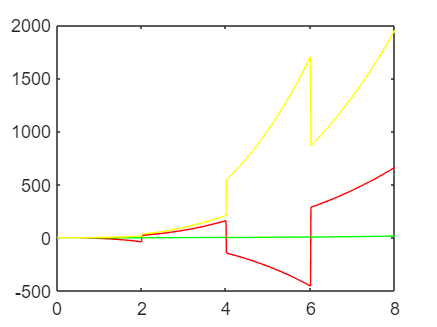

%%three knot points
A31 = getConstant3(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1));
A32 = getConstant3(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1));
A33 = getConstant3(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1));
A34 = getConstant3(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1));
A3 = [A31 A32 A33 A34];
 
B31 = getConstant3(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1));
B32 = getConstant3(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1));
B33 = getConstant3(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1));
B34 = getConstant3(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1));
B3 = [B31 B32 B33 B34];

C31 = getConstant3(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1));
C32 = getConstant3(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1));
C33 = getConstant3(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1));
C34 = getConstant3(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1));
C3 = [C31 C32 C33 C34];

D31 = getConstant3(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1));
D32 = getConstant3(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1));
D33 = getConstant3(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1));
D34 = getConstant3(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1));
D3 = [D31 D32 D33 D34];

x = 0:0.01:8;
q31A = A31(4) * x.^3 + A31(3) * x.^2 + A31(2) * x + A31(1);
q32A = A32(4) * x.^3 + A32(3) * x.^2 + A32(2) * x + A32(1);
q33A = A33(4) * x.^3 + A33(3) * x.^2 + A33(2) * x + A33(1);
q34A = A34(4) * x.^3 + A34(3) * x.^2 + A34(2) * x + A34(1);

q31B = B31(4) * x.^3 + B31(3) * x.^2 + B31(2) * x + B31(1);
q32B = B32(4) * x.^3 + B32(3) * x.^2 + B32(2) * x + B32(1);
q33B = B33(4) * x.^3 + B33(3) * x.^2 + B33(2) * x + B33(1);
q34B = B34(4) * x.^3 + B34(3) * x.^2 + B34(2) * x + B34(1);

q31C = C31(4) * x.^3 + C31(3) * x.^2 + C31(2) * x + C31(1);
q32C = C32(4) * x.^3 + C32(3) * x.^2 + C32(2) * x + C32(1);
q33C = C33(4) * x.^3 + C33(3) * x.^2 + C33(2) * x + C33(1);
q34C = C34(4) * x.^3 + C34(3) * x.^2 + C34(2) * x + C34(1);

q31D = D31(4) * x.^3 + D31(3) * x.^2 + D31(2) * x + D31(1);
q32D = D32(4) * x.^3 + D32(3) * x.^2 + D32(2) * x + D32(1);
q33D = D33(4) * x.^3 + D33(3) * x.^2 + D33(2) * x + D33(1);
q34D = D34(4) * x.^3 + D34(3) * x.^2 + D34(2) * x + D34(1);
figure; % Create a new figure window
y1 = q31A.*(x>=0&x<=2) + q31B.*(x>2&x<=4) + q31C.*(x>4&x<=6) + q31D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q32A.*(x>=0&x<=2) + q32B.*(x>2&x<=4) + q32C.*(x>4&x<=6) + q32D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q33A.*(x>=0&x<=2) + q33B.*(x>2&x<=4) + q33C.*(x>4&x<=6) + q33D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q34A.*(x>=0&x<=2) + q34B.*(x>2&x<=4) + q34C.*(x>4&x<=6) + q34D.*(x>6&x<=8);
plot(x, y1, 'y'); 

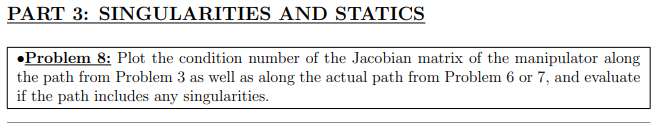


k=zeros(1,length(t1))

k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    J = [J(1:3,:);J(6,:)] ;% Remove rows that we do not wish to control
    k(i) = norm(inv(J))*norm(J); % calculate the condition number
end

T04 =    -0.0000   -0.7071    0.7071   45.3042
   -0.0000   -0.7071   -0.7071   45.3042
    1.0000   -0.0000         0  206.7110
         0         0         0    1.0000


T03 =     0.0101   -0.7070    0.7071   45.8023
    0.0101   -0.7070   -0.7071   45.8023
    0.9999    0.0143         0  205.9862
         0         0         0    1.0000


T02 =     0.4783   -0.5208    0.7071   48.4352
    0.4783   -0.5208   -0.7071   48.4352
    0.7365    0.6764         0  118.4977
         0         0         0    1.0000


T04 =     0.0000   -0.7089    0.7053  -40.7183
    0.0000   -0.7053   -0.7089  -40.5121
    1.0000    0.0000         0   -7.0145
         0         0         0    1.0000


T03 =    -0.5884   -0.3954    0.7053  -81.5444
   -0.5854   -0.3934   -0.7089  -81.1314
    0.5578   -0.8300         0  -18.3092
         0         0         0    1.0000


T02 =     0.4326    0.5616    0.7053  -52.2270
    0.4304    0.5587   -0.7089  -51.9625
   -0.7922    0.6103         0  -23.6733
         0         0         0    1.0000


T04 =     0.0000   -0.7142    0.6999   21.4056
    0.0000   -0.6999   -0.7142   20.9753
    1.0000    0.0000         0   17.1846
         0         0         0    1.0000


T03 =     0.6294    0.3376    0.6999  -21.2035
    0.6168    0.3308   -0.7142  -20.7772
   -0.4727    0.8812         0   -0.8166
         0         0         0    1.0000


T02 =     0.7024   -0.1298    0.6999   12.0740
    0.6882   -0.1272   -0.7142   11.8312
    0.1818    0.9833         0   66.9044
         0         0         0    1.0000


T04 =    -0.0000   -0.7231    0.6908   59.2090
   -0.0000   -0.6908   -0.7231   56.5648
    1.0000   -0.0000         0  226.0190
         0         0         0    1.0000


T03 =    -0.3131   -0.6518    0.6908   38.3194
   -0.2991   -0.6227   -0.7231   36.6081
    0.9014   -0.4330         0  236.1596
         0         0         0    1.0000


T02 =     0.3703   -0.6211    0.6908   57.7583
    0.3538   -0.5933   -0.7231   55.1789
    0.8589    0.5121         0  129.8794
         0         0         0    1.0000


T04 =     0.0000   -0.7352    0.6779    7.2207
    0.0000   -0.6779   -0.7352    6.6576
    1.0000    0.0000         0  242.2231
         0         0         0    1.0000


T03 = 4×4
   -0.4542    0.5781    0.6779   11.0495
   -0.4188    0.5330   -0.7352   10.1878
   -0.7864   -0.6178         0  198.8525
         0         0         0    1.0000


T02 = 4×4
   -0.1090   -0.7271    0.6779   67.6173
   -0.1005   -0.6704   -0.7352   62.3441
    0.9889   -0.1483         0  141.9722
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.7504    0.6610  -46.0593
   -0.0000   -0.6610   -0.7504  -40.5749
    1.0000   -0.0000         0   12.7663
         0         0         0    1.0000


T03 = 4×4
   -0.7066   -0.2524    0.6610  -91.2176
   -0.6225   -0.2224   -0.7504  -80.3562
    0.3364   -0.9417         0  -15.7348
         0         0         0    1.0000


T02 = 4×4
    0.5320    0.5292    0.6610  -49.2139
    0.4687    0.4662   -0.7504  -43.3539
   -0.7052    0.7090         0  -15.5863
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.7682    0.6402  -54.7592
   -0.0000   -0.6402   -0.7682  -45.6327
    1.0000   -0.0000         0  -47.2549
         0         0         0    1.0000


T03 = 4×4
    0.2507    0.7262    0.6402  -70.7007
    0.2089    0.6051   -0.7682  -58.9172
   -0.9452    0.3264         0  -37.1558
         0         0         0    1.0000


T02 = 4×4
    0.7679    0.0215    0.6402   -2.0015
    0.6399    0.0179   -0.7682   -1.6679
   -0.0280    0.9996         0   47.3946
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.7882    0.6154   64.0843
   -0.0000   -0.6154   -0.7882   50.0289
    1.0000   -0.0000         0  225.3949
         0         0         0    1.0000


T03 = 4×4
   -0.3516   -0.7055    0.6154   40.5124
   -0.2744   -0.5508   -0.7882   31.6270
    0.8950   -0.4460         0  235.4085
         0         0         0    1.0000


T02 = 4×4
    0.3809   -0.6901    0.6154   64.1821
    0.2973   -0.5388   -0.7882   50.1053
    0.8755    0.4832         0  131.4241
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8098    0.5867 -122.4230
    0.0000   -0.5867   -0.8098  -88.7015
    1.0000    0.0000         0    8.9859
         0         0         0    1.0000


T03 = 4×4
   -0.5018    0.6356    0.5867 -118.2771
   -0.3636    0.4605   -0.8098  -85.6976
   -0.7849   -0.6196         0  -34.5289
         0         0         0    1.0000


T02 = 4×4
    0.7593    0.2816    0.5867  -26.1869
    0.5501    0.2040   -0.8098  -18.9737
   -0.3477    0.9376         0   17.6618
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.8321    0.5547  -36.9077
   -0.0000   -0.5547   -0.8321  -24.6051
    1.0000   -0.0000         0  -10.8269
         0         0         0    1.0000


T03 = 4×4
   -0.6641   -0.5013    0.5547  -83.4143
   -0.4427   -0.3342   -0.8321  -55.6095
    0.6025   -0.7981         0  -18.6350
         0         0         0    1.0000


T02 = 4×4
    0.5361    0.6364    0.5547  -59.1807
    0.3574    0.4242   -0.8321  -39.4538
   -0.7648    0.6443         0  -21.1263
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8542    0.5200 -129.1326
    0.0000   -0.5200   -0.8542  -78.6138
    1.0000    0.0000         0    8.9859
         0         0         0    1.0000


T03 = 4×4
   -0.5293    0.6704    0.5200 -124.7594
   -0.3222    0.4081   -0.8542  -75.9515
   -0.7849   -0.6196         0  -34.5289
         0         0         0    1.0000


T02 = 4×4
    0.8009    0.2970    0.5200  -27.6221
    0.4876    0.1808   -0.8542  -16.8159
   -0.3477    0.9376         0   17.6618
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.8752    0.4837   71.1563
   -0.0000   -0.4837   -0.8752   39.3253
    1.0000   -0.0000         0  225.3949
         0         0         0    1.0000


T03 = 4×4
   -0.3903   -0.7834    0.4837   44.9831
   -0.2157   -0.4329   -0.8752   24.8604
    0.8950   -0.4460         0  235.4085
         0         0         0    1.0000


T02 = 4×4
    0.4229   -0.7663    0.4837   71.2649
    0.2337   -0.4235   -0.8752   39.3853
    0.8755    0.4832         0  131.4241
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.8944    0.4472  -63.7552
   -0.0000   -0.4472   -0.8944  -31.8776
    1.0000   -0.0000         0  -47.2549
         0         0         0    1.0000


T03 = 4×4
    0.2919    0.8454    0.4472  -82.3156
    0.1460    0.4227   -0.8944  -41.1578
   -0.9452    0.3264         0  -37.1558
         0         0         0    1.0000


T02 = 4×4
    0.8941    0.0251    0.4472   -2.3303
    0.4470    0.0125   -0.8944   -1.1652
   -0.0280    0.9996         0   47.3946
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.9111    0.4122  -55.9254
   -0.0000   -0.4122   -0.9111  -25.3009
    1.0000   -0.0000         0   12.7663
         0         0         0    1.0000


T03 = 4×4
   -0.8580   -0.3065    0.4122 -110.7568
   -0.3882   -0.1387   -0.9111  -50.1068
    0.3364   -0.9417         0  -15.7348
         0         0         0    1.0000


T02 = 4×4
    0.6460    0.6425    0.4122  -59.7557
    0.2922    0.2907   -0.9111  -27.0337
   -0.7052    0.7090         0  -15.5863
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9248    0.3804    9.0831
    0.0000   -0.3804   -0.9248    3.7361
    1.0000    0.0000         0  242.2231
         0         0         0    1.0000


T03 = 4×4
   -0.5713    0.7273    0.3804   13.8996
   -0.2350    0.2991   -0.9248    5.7171
   -0.7864   -0.6178         0  198.8525
         0         0         0    1.0000


T02 = 4×4
   -0.1371   -0.9146    0.3804   85.0580
   -0.0564   -0.3762   -0.9248   34.9859
    0.9889   -0.1483         0  141.9722
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.9354    0.3536   76.5965
   -0.0000   -0.3536   -0.9354   28.9528
    1.0000   -0.0000         0  226.0190
         0         0         0    1.0000


T03 = 4×4
   -0.4050   -0.8432    0.3536   49.5723
   -0.1531   -0.3187   -0.9354   18.7379
    0.9014   -0.4330         0  236.1596
         0         0         0    1.0000


T02 = 4×4
    0.4790   -0.8034    0.3536   74.7197
    0.1811   -0.3037   -0.9354   28.2434
    0.8589    0.5121         0  129.8794
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9428    0.3332   28.2564
    0.0000   -0.3332   -0.9428    9.9868
    1.0000    0.0000         0   17.1846
         0         0         0    1.0000


T03 = 4×4
    0.8309    0.4457    0.3332  -27.9896
    0.2937    0.1575   -0.9428   -9.8925
   -0.4727    0.8812         0   -0.8166
         0         0         0    1.0000


T02 = 4×4
    0.9271   -0.1714    0.3332   15.9382
    0.3277   -0.0606   -0.9428    5.6331
    0.1818    0.9833         0   66.9044
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9472    0.3205  -54.4079
    0.0000   -0.3205   -0.9472  -18.4115
    1.0000    0.0000         0   -7.0145
         0         0         0    1.0000


T03 = 4×4
   -0.7862   -0.5284    0.3205 -108.9600
   -0.2660   -0.1788   -0.9472  -36.8718
    0.5578   -0.8300         0  -18.3092
         0         0         0    1.0000


T02 = 4×4
    0.5781    0.7504    0.3205  -69.7859
    0.1956    0.2539   -0.9472  -23.6154
   -0.7922    0.6103         0  -23.6733
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.9487    0.3162   60.7820
   -0.0000   -0.3162   -0.9487   20.2607
    1.0000   -0.0000         0  206.7110
         0         0         0    1.0000


T03 = 4×4
    0.0136   -0.9486    0.3162   61.4502
    0.0045   -0.3162   -0.9487   20.4834
    0.9999    0.0143         0  205.9862
         0         0         0    1.0000


T02 = 4×4
    0.6417   -0.6987    0.3162   64.9826
    0.2139   -0.2329   -0.9487   21.6609
    0.7365    0.6764         0  118.4977
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9472    0.3205  -69.7191
    0.0000   -0.3205   -0.9472  -23.5928
    1.0000    0.0000         0    7.3232
         0         0         0    1.0000


T03 = 4×4
   -0.8654   -0.3852    0.3205 -126.8441
   -0.2928   -0.1304   -0.9472  -42.9237
    0.4067   -0.9136         0  -15.8303
         0         0         0    1.0000


T02 = 4×4
    0.5862    0.7441    0.3205  -69.1989
    0.1984    0.2518   -0.9472  -23.4167
   -0.7855    0.6188         0  -23.0536
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9428    0.3332   41.1673
    0.0000   -0.3332   -0.9428   14.5500
    1.0000    0.0000         0   57.0812
         0         0         0    1.0000


T03 = 4×4
    0.9137    0.2325    0.3332  -14.3741
    0.3229    0.0822   -0.9428   -5.0803
   -0.2466    0.9691         0   22.0702
         0         0         0    1.0000


T02 = 4×4
    0.9294   -0.1584    0.3332   14.7318
    0.3285   -0.0560   -0.9428    5.2067
    0.1680    0.9858         0   65.6248
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9354    0.3536   87.3552
    0.0000   -0.3536   -0.9354   33.0195
    1.0000    0.0000         0  236.8654
         0         0         0    1.0000


T03 = 4×4
   -0.4888   -0.7975    0.3536   53.7431
   -0.1848   -0.3015   -0.9354   20.3144
    0.8526   -0.5226         0  245.4878
         0         0         0    1.0000


T02 = 4×4
    0.5656   -0.7450    0.3536   69.2851
    0.2138   -0.2816   -0.9354   26.1892
    0.7964    0.6047         0  124.0696
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9248    0.3804   46.2021
    0.0000   -0.3804   -0.9248   19.0038
    1.0000    0.0000         0  283.1454
         0         0         0    1.0000


T03 = 4×4
   -0.8007    0.4628    0.3804   31.5764
   -0.3293    0.1904   -0.9248   12.9880
   -0.5004   -0.8658         0  224.0041
         0         0         0    1.0000


T02 = 4×4
    0.1631   -0.9103    0.3804   84.6599
    0.0671   -0.3744   -0.9248   34.8222
    0.9843    0.1764         0  141.5417
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.9111    0.4122   57.4463
    0.0000   -0.4122   -0.9111   25.9889
    1.0000    0.0000         0  172.1003
         0         0         0    1.0000


T03 = 4×4
   -0.1482    0.8990    0.4122   63.5532
   -0.0671    0.4067   -0.9111   28.7517
   -0.9867   -0.1627         0  162.7505
         0         0         0    1.0000


T02 = 4×4
   -0.0641   -0.9088    0.4122   84.5222
   -0.0290   -0.4112   -0.9111   38.2382
    0.9975   -0.0704         0  142.7694
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.8944    0.4472  -77.0552
   -0.0000   -0.4472   -0.8944  -38.5276
    1.0000   -0.0000         0  -44.0472
         0         0         0    1.0000


T03 = 4×4
   -0.2185   -0.8673    0.4472  -90.3156
   -0.1092   -0.4337   -0.8944  -45.1578
    0.9697   -0.2443         0  -35.1875
         0         0         0    1.0000


T02 = 4×4
    0.1431    0.8829    0.4472  -82.1106
    0.0715    0.4415   -0.8944  -41.0553
   -0.9871    0.1600         0  -41.8025
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8752    0.4837  -79.2240
    0.0000   -0.4837   -0.8752  -43.7839
    1.0000    0.0000         0  -36.0707
         0         0         0    1.0000


T03 = 4×4
   -0.3185   -0.8152    0.4837  -99.8525
   -0.1760   -0.4505   -0.8752  -55.1845
    0.9314   -0.3639         0  -25.7443
         0         0         0    1.0000


T02 = 4×4
    0.1412    0.8638    0.4837  -80.3303
    0.0780    0.4774   -0.8752  -44.3954
   -0.9869    0.1613         0  -41.7819
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8542    0.5200  -79.6833
    0.0000   -0.5200   -0.8542  -48.5099
    1.0000    0.0000         0  -33.5561
         0         0         0    1.0000


T03 = 4×4
   -0.3128   -0.7948    0.5200  -99.9670
   -0.1904   -0.4839   -0.8542  -60.8583
    0.9305   -0.3662         0  -23.2230
         0         0         0    1.0000


T02 = 4×4
    0.1149    0.8464    0.5200  -78.7149
    0.0700    0.5153   -0.8542  -47.9204
   -0.9909    0.1346         0  -42.1542
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8321    0.5547  -78.4066
    0.0000   -0.5547   -0.8321  -52.2711
    1.0000    0.0000         0  -33.1784
         0         0         0    1.0000


T03 = 4×4
   -0.2955   -0.7778    0.5547  -97.4625
   -0.1970   -0.5186   -0.8321  -64.9750
    0.9348   -0.3551         0  -22.8854
         0         0         0    1.0000


T02 = 4×4
    0.1004    0.8260    0.5547  -76.8149
    0.0670    0.5506   -0.8321  -51.2099
   -0.9927    0.1207         0  -42.3200
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.8098    0.5867  -75.5430
    0.0000   -0.5867   -0.8098  -54.7347
    1.0000    0.0000         0  -33.5561
         0         0         0    1.0000


T03 = 4×4
   -0.2966   -0.7535    0.5867  -94.7729
   -0.2149   -0.5460   -0.8098  -68.6676
    0.9305   -0.3662         0  -23.2230
         0         0         0    1.0000


T02 = 4×4
    0.1090    0.8024    0.5867  -74.6250
    0.0789    0.5814   -0.8098  -54.0695
   -0.9909    0.1346         0  -42.1542
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7882    0.6154  -71.3502
    0.0000   -0.6154   -0.7882  -55.7012
    1.0000    0.0000         0  -36.0707
         0         0         0    1.0000


T03 = 4×4
   -0.2868   -0.7342    0.6154  -89.9285
   -0.2239   -0.5732   -0.7882  -70.2048
    0.9314   -0.3639         0  -25.7443
         0         0         0    1.0000


T02 = 4×4
    0.1272    0.7779    0.6154  -72.3466
    0.0993    0.6073   -0.7882  -56.4790
   -0.9869    0.1613         0  -41.7819
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.7682    0.6402  -66.1825
   -0.0000   -0.6402   -0.7682  -55.1521
    1.0000   -0.0000         0  -44.0472
         0         0         0    1.0000


T03 = 4×4
   -0.1876   -0.7450    0.6402  -77.5719
   -0.1564   -0.6208   -0.7682  -64.6432
    0.9697   -0.2443         0  -35.1875
         0         0         0    1.0000


T02 = 4×4
    0.1229    0.7583    0.6402  -70.5246
    0.1024    0.6319   -0.7682  -58.7705
   -0.9871    0.1600         0  -41.8025
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7504    0.6610   47.3119
    0.0000   -0.6610   -0.7504   41.6784
    1.0000    0.0000         0  172.1003
         0         0         0    1.0000


T03 = 4×4
   -0.1221    0.7404    0.6610   52.3414
   -0.1075    0.6522   -0.7504   46.1091
   -0.9867   -0.1627         0  162.7505
         0         0         0    1.0000


T02 = 4×4
   -0.0528   -0.7485    0.6610   69.6111
   -0.0465   -0.6594   -0.7504   61.3225
    0.9975   -0.0704         0  142.7694
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7352    0.6779   36.7286
    0.0000   -0.6779   -0.7352   33.8643
    1.0000    0.0000         0  283.1454
         0         0         0    1.0000


T03 = 4×4
   -0.6365    0.3679    0.6779   25.1018
   -0.5869    0.3392   -0.7352   23.1442
   -0.5004   -0.8658         0  224.0041
         0         0         0    1.0000


T02 = 4×4
    0.1297   -0.7237    0.6779   67.3008
    0.1196   -0.6672   -0.7352   62.0523
    0.9843    0.1764         0  141.5417
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7231    0.6908   67.5255
    0.0000   -0.6908   -0.7231   64.5099
    1.0000    0.0000         0  236.8654
         0         0         0    1.0000


T03 = 4×4
   -0.3779   -0.6165    0.6908   41.5433
   -0.3610   -0.5889   -0.7231   39.6881
    0.8526   -0.5226         0  245.4878
         0         0         0    1.0000


T02 = 4×4
    0.4372   -0.5759    0.6908   53.5573
    0.4177   -0.5502   -0.7231   51.1656
    0.7964    0.6047         0  124.0696
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7142    0.6999   31.1862
    0.0000   -0.6999   -0.7142   30.5593
    1.0000    0.0000         0   57.0812
         0         0         0    1.0000


T03 = 4×4
    0.6922    0.1761    0.6999  -10.8891
    0.6783    0.1726   -0.7142  -10.6702
   -0.2466    0.9691         0   22.0702
         0         0         0    1.0000


T02 = 4×4
    0.7041   -0.1200    0.6999   11.1600
    0.6899   -0.1176   -0.7142   10.9357
    0.1680    0.9858         0   65.6248
         0         0         0    1.0000


T04 = 4×4
    0.0000   -0.7089    0.7053  -52.1770
    0.0000   -0.7053   -0.7089  -51.9128
    1.0000    0.0000         0    7.3232
         0         0         0    1.0000


T03 = 4×4
   -0.6476   -0.2883    0.7053  -94.9287
   -0.6443   -0.2868   -0.7089  -94.4479
    0.4067   -0.9136         0  -15.8303
         0         0         0    1.0000


T02 = 4×4
    0.4387    0.5569    0.7053  -51.7877
    0.4365    0.5540   -0.7089  -51.5254
   -0.7855    0.6188         0  -23.0536
         0         0         0    1.0000


T04 = 4×4
   -0.0000   -0.7071    0.7071   45.3042
   -0.0000   -0.7071   -0.7071   45.3042
    1.0000   -0.0000         0  206.7110
         0         0         0    1.0000


T03 = 4×4
    0.0101   -0.7070    0.7071   45.8023
    0.0101   -0.7070   -0.7071   45.8023
    0.9999    0.0143         0  205.9862
         0         0         0    1.0000


T02 = 4×4
    0.4783   -0.5208    0.7071   48.4352
    0.4783   -0.5208   -0.7071   48.4352
    0.7365    0.6764         0  118.4977
         0         0         0    1.0000


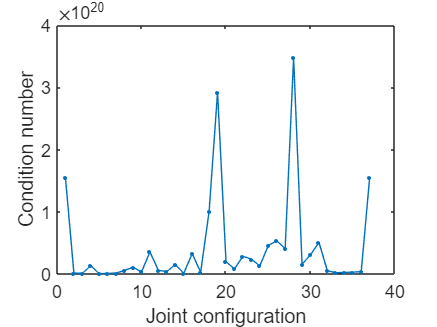

figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')

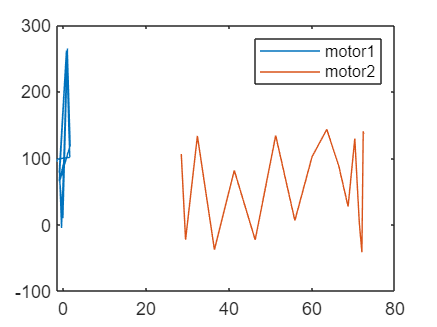

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);
end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])


disp("Motor 4 is omitted here as the torques are smaller than")

Motor 4 is omitted here as the torques are smaller than